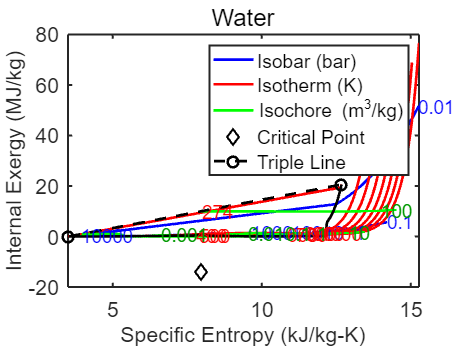


% Make T-s, u-s, h-s diagrams for water.
% C.F. Edwards, 10/30/12
%
% Update 1/10/2022
% New version of Cantera doesn't allow you to set state with Tsat/Psat pair
% (previous versions accepted it and assumed quality of 0)
% Adjusted any set calls that make new Cantera unhappy
% clear all
% format compact
% fprintf('\n********************************************************\n')
% % Set up a water object to work with in Cantera.
% water = Solution('liquidvapor.xml','water');
% % Get the critical point props.
% Tc = critTemperature(water);
% Pc = critPressure(water);
% set(water,'T',Tc,'P',Pc)
% sc = entropy_mass(water);
% uc = intEnergy_mass(water);
% hc = enthalpy_mass(water);
% xc = exergy_mass(water);
% % Set the triple point props.  Use a value epsilon above Tt to get the
% % bottom edge of the vapor dome.
% Tt = 273.165;
% Pt = satPressure(water,Tt);
% setState_Tsat(water,[Tt 0]);
% sft = entropy_mass(water);
% uft = intEnergy_mass(water);
% hft = enthalpy_mass(water);
% xft = exergy_mass(water);
% vft = 1/density(water);
% setState_Tsat(water,[Tt 1]);
% sgt = entropy_mass(water);
% ugt = intEnergy_mass(water);
% hgt = enthalpy_mass(water);
% xgt = exergy_mass(water);
% vgt = 1/density(water);
% % Set the limits for data curves.
% Tmin = Tt;
% Tmax = 1100;
% Pmin = Pt;
% Pmax = 10000*1e5;
% % Make a vapor dome.
% dT = (Tc-Tmin)/150;
% i = 1;
% %setState_Tsat(water,[Tmin 0]);
% for T=Tmin:dT:Tc-dT    % Stop short of the critical point.
%     Tsatline(i) = T;
%     setState_Tsat(water,[T 0]);
%     sliqline(i) = entropy_mass(water);
%     uliqline(i) = intEnergy_mass(water);
%     hliqline(i) = enthalpy_mass(water);
%     xliqline(i) = exergy_mass(water);
%     setState_Tsat(water,[T 1]);
%     svapline(i) = entropy_mass(water);
%     uvapline(i) = intEnergy_mass(water);
%     hvapline(i) = enthalpy_mass(water);
%     xvapline(i) = exergy_mass(water);
%     i = i+1;
% end
% Tsatline(i) = Tc;   % Add the critical point now.
% sliqline(i) = sc;
% uliqline(i) = uc;
% hliqline(i) = hc;
% xliqline(i) = xc;
% svapline(i) = sc;
% uvapline(i) = uc;
% hvapline(i) = hc;
% xvapline(i) = xc;
% % Start a set of isobaric curves.
% Plist = [0.01 0.1 1 10 100];  % Pressure in bar
% for j=1:1:length(Plist)
%     water = Solution('liquidvapor.xml','water');
%     P = Plist(j)*100000;
%     % Do the compressed liquid side.
%     setState_Psat(water,[P 0]);
%     Tsat = temperature(water);
%     dT = (Tsat - Tmin)/100;
%     i = 1;
%     for T=Tmin:dT:Tsat-dT  % Stop short of saturation.
%         Tpresline(j,i) = T;
%         set(water,'T',T,'P',P);
%         spresline(j,i) = entropy_mass(water);
%         upresline(j,i) = intEnergy_mass(water);
%         hpresline(j,i) = enthalpy_mass(water);
%         xpresline(j,i) = exergy_mass(water);
%         i = i+1;
%     end
%     Tpresline(j,i) = Tsat;   % Add the saturation point now.
%     setState_Psat(water,[P 0]);
%     spresline(j,i) = entropy_mass(water);
%     upresline(j,i) = intEnergy_mass(water);
%     hpresline(j,i) = enthalpy_mass(water);
%     xpresline(j,i) = exergy_mass(water);
%     i = i+1;
%     % Now go across the dome.
%     dq = 1/100;
%     for q=0+dq:dq:1-dq  % Stop short of saturation.
%         Tpresline(j,i) = Tsat;
%         setState_Psat(water,[P q]);
%         spresline(j,i) = entropy_mass(water);
%         upresline(j,i) = intEnergy_mass(water);
%         hpresline(j,i) = enthalpy_mass(water);
%         xpresline(j,i) = exergy_mass(water);
%         i = i+1;
%     end
%     Tpresline(j,i) = Tsat;   % Add the saturation point now.
%     setState_Psat(water,[P 1]);
%     spresline(j,i) = entropy_mass(water);
%     upresline(j,i) = intEnergy_mass(water);
%     hpresline(j,i) = enthalpy_mass(water);
%     xpresline(j,i) = exergy_mass(water);
%     i = i+1;
%     % Do the vapor side.
%     dT = (Tmax - Tsat)/100;
%     for T=Tsat+dT:dT:Tmax  % Start just above saturation.
%         try
%             set(water,'T',T,'P',P);
%             Tpresline(j,i) = T;
%             spresline(j,i) = entropy_mass(water);
%             upresline(j,i) = intEnergy_mass(water);
%             hpresline(j,i) = enthalpy_mass(water);
%             xpresline(j,i) = exergy_mass(water);
%         catch
%             disp('Trouble finding isobar...')
%             water = Solution('liquidvapor.xml','water');
%             Tpresline(j,i) = Tpresline(j,i-1);
%             spresline(j,i) = spresline(j,i-1);
%             upresline(j,i) = upresline(j,i-1);
%             hpresline(j,i) = hpresline(j,i-1);
%             xpresline(j,i) = xpresline(j,i-1);
%         end
%         i = i+1;
%     end
% end
% % Add an isobar above the critical pressure.
% P = 1000;           % In bar
% Plist = [Plist P];  % Add to the list
% P = P*100000;       % In Pascals
% j = length(Plist);
% dT = (Tmax - Tmin)/300;
% i = 1;
% for T=Tmin:dT:Tmax  % Stop short of saturation.
%     Tpresline(j,i) = T;
%     set(water,'T',T,'P',P);
%     spresline(j,i) = entropy_mass(water);
%     upresline(j,i) = intEnergy_mass(water);
%     hpresline(j,i) = enthalpy_mass(water);
%     xpresline(j,i) = exergy_mass(water);
%     i = i+1;
% end
% % Add an isobar above the critical pressure.
% P = 10000;           % In bar
% Plist = [Plist P];  % Add to the list
% P = P*100000;       % In Pascals
% j = length(Plist);
% dT = (Tmax - Tmin)/300;
% i = 1;
% for T=Tmax:-dT:Tmin  % Stop short of saturation.
%     set(water,'T',T,'P',P);
%     if T > 340
%         Tpresline(j,i) = T;
%         spresline(j,i) = entropy_mass(water);
%         upresline(j,i) = intEnergy_mass(water);
%         hpresline(j,i) = enthalpy_mass(water);
%         xpresline(j,i) = exergy_mass(water);
%     else
%         % Can't do liquids when too dense.
%         Tpresline(j,i) = Tpresline(j,i-1);
%         spresline(j,i) = spresline(j,i-1);
%         upresline(j,i) = upresline(j,i-1);
%         hpresline(j,i) = hpresline(j,i-1);
%         xpresline(j,i) = exergy_mass(water);
%     end
%     i = i+1;
% end
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Start a set of isotherms.
% Tlist = [274 400 500 600 700 800 900 1000];
% for j=1:1:3    % Do the part of list below the critical point. 
%     water = Solution('liquidvapor.xml','water');
%     T = Tlist(j);
%     % Do the compressed liquid side.
%     setState_Tsat(water,[T 0]);
%     Psat = pressure(water);
%     logdP = (log(Pmax) - log(Psat))/100;
%     i = 1;
%     for logP=log(Pmax):-logdP:log(Psat)+logdP  % Stop short of saturation.
%         P = exp(logP);
%         Ttempline(j,i) = T;
%         set(water,'T',T,'P',P);
%         stempline(j,i) = entropy_mass(water);
%         utempline(j,i) = intEnergy_mass(water);
%         htempline(j,i) = enthalpy_mass(water);
%         xtempline(j,i) = exergy_mass(water);
%         i = i+1;
%     end
%     Ttempline(j,i) = T;   % Add the saturation point now.
%     set(water,'T',T,'Vapor',0);
%     stempline(j,i) = entropy_mass(water);
%     utempline(j,i) = intEnergy_mass(water);
%     htempline(j,i) = enthalpy_mass(water);
%     xtempline(j,i) = exergy_mass(water);
%     i = i+1;
%     % Now go across the dome.
%     dq = 1/100;
%     for q=0+dq:dq:1-dq  % Stop short of saturation.
%         Ttempline(j,i) = T;
%         setState_Psat(water,[Psat q]);
%         stempline(j,i) = entropy_mass(water);
%         utempline(j,i) = intEnergy_mass(water);
%         htempline(j,i) = enthalpy_mass(water);
%         xtempline(j,i) = exergy_mass(water);
%         i = i+1;
%     end
%     Ttempline(j,i) = T; % Add the saturation point now.
%     setState_Psat(water,[Psat 1]);
%     stempline(j,i) = entropy_mass(water);
%     utempline(j,i) = intEnergy_mass(water);
%     htempline(j,i) = enthalpy_mass(water);
%     xtempline(j,i) = exergy_mass(water);
%     i = i+1;
%     % Do the vapor side.
%     logdP = (log(Psat) - log(Pmin))/100;
%     for logP=log(Psat)-logdP:-logdP:log(Pmin)  % Stop short of saturation.
%         P = exp(logP);
%         Ttempline(j,i) = T;
%         set(water,'T',T,'P',P);
%         stempline(j,i) = entropy_mass(water);
%         utempline(j,i) = intEnergy_mass(water);
%         htempline(j,i) = enthalpy_mass(water);
%         xtempline(j,i) = exergy_mass(water);
%         i = i+1;
%     end
% end
% % Add isotherms above the critical temperature.
% for j=j+1:1:length(Tlist)
%     water = Solution('liquidvapor.xml','water');
%     T = Tlist(j);
%     logdP = (log(Pmax) - log(Pmin))/300;
%     i = 1;
%     for logP=log(Pmax):-logdP:log(Pmin)  % Stop short of saturation.
%         P = exp(logP);
%         Ttempline(j,i) = T;
%         set(water,'T',T,'P',P);
%         stempline(j,i) = entropy_mass(water);
%         utempline(j,i) = intEnergy_mass(water);
%         htempline(j,i) = enthalpy_mass(water);
%         xtempline(j,i) = exergy_mass(water);
%         i = i+1;
%     end
% end
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Start a set of isochores.
% set(water,'T',Tmin,'Vapor',0);
% vmin = 1/density(water);
% vmax = vgt;
% set(water,'T',Tmax,'V',vmin);
% vlist = [0.001 0.01 0.1 1 10 100];
% for j=1:1:length(vlist)
%     v = vlist(j);
%     dT = (Tmax - Tmin)/300;
%     i = 1;
%     for T=Tmin:dT:Tmax  % Stop short of saturation.
%         Tvoluline(j,i) = T;
%         set(water,'T',T,'V',v);
%         svoluline(j,i) = entropy_mass(water);
%         uvoluline(j,i) = intEnergy_mass(water);
%         hvoluline(j,i) = enthalpy_mass(water);
%         xvoluline(j,i) = exergy_mass(water);
%         i = i+1;
%     end
% end
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Start a set of isoergs.
% ulist = [-13 -13.25 -13.5 -14 -14.5 -15 -15.5]*1e6;
% vmax  = [100    100   100 100   100  70    40];
% vmin = .001001;
% for j=1:1:length(ulist)
%     u = ulist(j)
%     lvhigh = log(vmax(j));
%     lvlow  = log(vmin);
%     ldv = (lvhigh - lvlow)/300;
%     i = 1;
%     for lv=lvhigh:-ldv:lvlow  % Stop short of saturation.
%         v = exp(lv);
%         try
%             setState_UV(water,[u,v]);
%             Terguline(j,i) = temperature(water);
%             serguline(j,i) = entropy_mass(water);
%             if(Terguline(j,i) > Tmax)
%                 Terguline(j,i) = Terguline(j,i-1);
%                 serguline(j,i) = serguline(j,i-1);
%             end
%         catch
%             disp('Trouble finding isoerg...')
%             water = Solution('liquidvapor.xml','water');
%             Terguline(j,i) = Terguline(j,i-1);
%             serguline(j,i) = serguline(j,i-1);
%         end
%         i = i+1;
%     end
% end
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Start a set of isenthalps.
% hlist = [-13 -13.25 -13.5 -14 -14.5 -15 -15.5]*1e6;
% Pmax  = 10000e5;
% Pmin = .01e5;
% for j=1:1:length(hlist)
%     h = hlist(j)
%     lPhigh = log(Pmax);
%     lPlow  = log(Pmin);
%     ldP = (lPhigh - lPlow)/300;
%     i = 1;
%     for lP=lPlow:ldP:lPhigh  % Stop short of saturation.
%         P = exp(lP);
%         try
%             setState_HP(water,[h,P]);
%             Tenthline(j,i) = temperature(water);
%             senthline(j,i) = entropy_mass(water);
%             if(Tenthline(j,i) < Tmin)
%                 Tenthline(j,i) = Tenthline(j,i-1);
%                 senthline(j,i) = senthline(j,i-1);
%             end
%         catch
%             disp('Trouble finding isenthalp...')
%             water = Solution('liquidvapor.xml','water');
%             Tenthline(j,i) = Tenthline(j,i-1);
%             senthline(j,i) = senthline(j,i-1);
%         end
%         i = i+1;
%     end
% end

%%% MAKE PLOTS %%%
% % PLOT 1
% figure(1)
% clf
% hold on
% i = 1;
% plot(spresline(i,:)/1000,Tpresline(i,:),'b')
% plot(svoluline(i,:)/1000,Tvoluline(i,:),'-','Color',[0 .6 0])
% plot(serguline(i,:)/1000,Terguline(i,:),'r')
% plot(senthline(i,:)/1000,Tenthline(i,:),'m')
% plot(sc/1000,Tc,'kd')
% plot([sft/1000 sgt/1000],[Tt Tt],'ko--')
% for i=1:1:length(Plist)
%     plot(spresline(i,:)/1000,Tpresline(i,:),'b')
% end
% for i=1:1:length(vlist)
%     plot(svoluline(i,:)/1000,Tvoluline(i,:),'-','Color',[0 .6 0])
% end
% for i=1:1:length(ulist)
%     plot(serguline(i,:)/1000,Terguline(i,:),'r')
% end
% for i=1:1:length(ulist)
%     plot(senthline(i,:)/1000,Tenthline(i,:),'m')
% end
% plot(sliqline/1000,Tsatline,'k')
% plot(svapline/1000,Tsatline,'k')
% plot([sft/1000 sgt/1000],[Tt Tt],'ko--')
% hold off
% xlabel('Specific Entropy (kJ/kg-K)')
% ylabel('Temperature (K)')
% for i=1:1:length(Plist)
%     text(spresline(i,150)/1000,Tpresline(i,150),num2str(Plist(i)),'Color','b')
% end
% for i=1:1:length(vlist)
%     text(svoluline(i,150)/1000,Tvoluline(i,150),num2str(vlist(i)),'Color',[0 .6 0])
% end
% for i=1:1:length(ulist)
%     text(serguline(i,1)/1000,Terguline(i,1),num2str(ulist(i)/1e6),'Color','r')
% end
% for i=1:1:length(ulist)
%     text(senthline(i,1)/1000,Tenthline(i,1),num2str(hlist(i)/1e6),'Color','m')
% end
% legend('Isobar (bar)','Isochore (m^3/kg)','Isoenergy (MJ/kg)','Isenthalp (MJ/kg)','Critical Point','Triple Line')
% title('Water')
% scale = axis;
% axis([scale(1) scale(2) 200 1000])
% plotfixer
% % PLOT 2
% figure(2)
% clf
% hold on
% i = 1;
% plot(spresline(i,:)/1000,upresline(i,:)/1e6,'b')
% plot(stempline(i,:)/1000,utempline(i,:)/1e6,'r')
% plot(svoluline(i,:)/1000,uvoluline(i,:)/1e6,'g')
% plot(sc/1000,uc/1e6,'kd')
% plot([sft/1000 sgt/1000],[uft/1e6 ugt/1e6],'ko--')
% for i=1:1:length(Plist)
%     plot(spresline(i,:)/1000,upresline(i,:)/1e6,'b')
% end
% for i=1:1:length(Tlist)
%     plot(stempline(i,:)/1000,utempline(i,:)/1e6,'r')
% end
% for i=1:1:length(vlist)
%     plot(svoluline(i,:)/1000,uvoluline(i,:)/1e6,'g')
% end
% plot(sliqline/1000,uliqline/1e6,'k')
% plot(svapline/1000,uvapline/1e6,'k')
% plot([sft/1000 sgt/1000],[uft/1e6 ugt/1e6],'ko--')
% hold off
% xlabel('Specific Entropy (kJ/kg-K)')
% ylabel('Specific Internal Energy (MJ/kg)')
% for i=1:1:length(Plist)
%     text(spresline(i,150)/1000,upresline(i,150)/1e6,...
%         num2str(Plist(i)),'Color','b')
% end
% for i=1:1:length(Tlist)
%     text(stempline(i,150)/1000,utempline(i,150)/1e6,...
%         num2str(Tlist(i)),'Color','r')
% end
% for i=1:1:length(vlist)
%     text(svoluline(i,150)/1000,uvoluline(i,150)/1e6,...
%         num2str(vlist(i)),'Color',[0 .6 0])
% end
% legend('Isobar (bar)','Isotherm (K)','Isochore (m^3/kg)',...
%     'Critical Point','Triple Line')
% title('Water')
% plotfixer
% % PLOT 3
% figure(3)
% clf
% hold on
% i = 1;
% plot(spresline(i,:)/1000,hpresline(i,:)/1e6,'b')
% plot(stempline(i,:)/1000,htempline(i,:)/1e6,'r')
% plot(svoluline(i,:)/1000,hvoluline(i,:)/1e6,'g')
% plot(sc/1000,hc/1e6,'kd')
% plot([sft/1000 sgt/1000],[hft/1e6 hgt/1e6],'ko--')
% for i=1:1:length(Plist)
%     plot(spresline(i,:)/1000,hpresline(i,:)/1e6,'b')
% end
% for i=1:1:length(Tlist)
%     plot(stempline(i,:)/1000,htempline(i,:)/1e6,'r')
% end
% for i=1:1:length(vlist)
%     plot(svoluline(i,:)/1000,hvoluline(i,:)/1e6,'g')
% end
% plot(sliqline/1000,hliqline/1e6,'k')
% plot(svapline/1000,hvapline/1e6,'k')
% plot([sft/1000 sgt/1000],[hft/1e6 hgt/1e6],'ko--')
% hold off
% scale = axis;
% axis([scale(1) scale(2) scale(3) -11.5])
% xlabel('Specific Entropy (kJ/kg-K)')
% ylabel('Specific Enthalpy (MJ/kg)')
% for i=1:1:length(Plist)
%     text(spresline(i,300)/1000,hpresline(i,300)/1e6,...
%         num2str(Plist(i)),'Color','b')
% end
% for i=1:1:length(Tlist)
%     text(stempline(i,150)/1000,htempline(i,150)/1e6,...
%         num2str(Tlist(i)),'Color','r')
% end
% for i=1:1:length(vlist)
%     text(svoluline(i,200)/1000,hvoluline(i,200)/1e6,...
%         num2str(vlist(i)),'Color',[0 .6 0])
% end
% legend('Isobar (bar)','Isotherm (K)','Isochore (m^3/kg)',...
%     'Critical Point','Triple Line')
% title('Water')
% plotfixer

% PLOT 4
figure(1)
clf
hold on
i = 1;
plot(spresline(i,:)/1000,xpresline(i,:)/1e6,'b')
plot(stempline(i,:)/1000,xtempline(i,:)/1e6,'r')
plot(svoluline(i,:)/1000,xvoluline(i,:)/1e6,'g')
plot(sc/1000,hc/1e6,'kd')
plot([sft/1000 sgt/1000],[xft/1e6 xgt/1e6],'ko--')
for i=1:1:length(Plist)
    plot(spresline(i,:)/1000,xpresline(i,:)/1e6,'b')
end
for i=1:1:length(Tlist)
    plot(stempline(i,:)/1000,xtempline(i,:)/1e6,'r')
end
for i=1:1:length(vlist)
    plot(svoluline(i,:)/1000,xvoluline(i,:)/1e6,'g')
end
plot(sliqline/1000,xliqline/1e6,'k')
plot(svapline/1000,xvapline/1e6,'k')
plot([sft/1000 sgt/1000],[xft/1e6 xgt/1e6],'ko--')
hold off
%scale = axis;
%axis([scale(1) scale(2) scale(3) -11.5])
xlabel('Specific Entropy (kJ/kg-K)')
ylabel('Internal Exergy (MJ/kg)')
for i=1:1:length(Plist)
    text(spresline(i,300)/1000,xpresline(i,300)/1e6,...
        num2str(Plist(i)),'Color','b')
end
for i=1:1:length(Tlist)
    text(stempline(i,150)/1000,xtempline(i,150)/1e6,...
        num2str(Tlist(i)),'Color','r')
end
for i=1:1:length(vlist)
    text(svoluline(i,200)/1000,xvoluline(i,200)/1e6,...
        num2str(vlist(i)),'Color',[0 .6 0])
end
legend('Isobar (bar)','Isotherm (K)','Isochore (m^3/kg)',...
    'Critical Point','Triple Line')
title('Water')
plotfixer

function [X_tm, X_c] = exergy_calc(gas)
    % Dead State
    T0 = 25+273.15;
    P0 = oneatm;
    R = 8.314; % universal gas constant
    dead = GRI30;  
    set(dead, "T", T0, "P", P0, 'X', 'N2:0.757223,O2:0.202157,H2O:0.031208,Ar:0.009015,CO2:0.000397')
    
    % Thermo-Mechanical Equillibrium
    P_in = pressure(gas);
    T_in = temperature(gas);
    H_in = enthalpy_mass(gas);
    tm_eq = gas; 
    set(tm_eq, "T", T0, "P", P0);
    gibbs_tm = gibbs_mass(tm_eq);
    U_tm = intEnergy_mass(tm_eq);
    rho_tm = 1/density(tm_eq);
    S_tm = entropy_mass(tm_eq);
    try
        set(gas, "T", T_in, "P", P_in); % Return gas to normal
    catch
        setState_TH(gas,[T_in, H_in])
    end
    
    % Thermo-Mechanical Exergy
    X_tm = (intEnergy_mass(gas)-U_tm) + P0*(1/density(gas) - rho_tm) - T0*(entropy_mass(gas)-S_tm); % J/kg
    
    

    if size(moleFractions(gas),1)>1 % Object is likely GRI30
        mu = chemPotentials(dead);
    
        % Decomposing Input to Environmental 
        % [ C, H, N, O, Ar]
        mm_all = molecularWeights(gas);
        mm = [mm_all(speciesIndex(gas,'C')), mm_all(speciesIndex(gas,'H')), mm_all(speciesIndex(gas,'N')), mm_all(speciesIndex(gas,'O')), mm_all(speciesIndex(gas,'Ar'))]; % molar masses (g/mol)
        mass_frac = [ elementalMassFraction(gas,'C'),  elementalMassFraction(gas,'H'),  elementalMassFraction(gas,'N'), elementalMassFraction(gas,'O'),  elementalMassFraction(gas,'Ar')];
        mole_frac = (mass_frac./mm)./(sum(mass_frac./mm)); % normalize to 1mol of elements
        avg_atoms = meanMolecularWeight(gas)/sum(mm.*mole_frac); % average atoms per molecule
        comb_frac = mole_frac*avg_atoms; % atoms of each element from combusting a mole of input gas
    
        % Assign Inputs and Outputs
        n_out_co2 = comb_frac(1);
        n_out_h20 = comb_frac(2)/2;
        n_in_o2 = max(n_out_h20/2 + n_out_co2 - (comb_frac(4)/2), 0);
        n_out_o2 = max((comb_frac(4)/2) - n_out_h20/2 - n_out_co2 , 0);
        n_in_n2 = 3.76*n_in_o2;
        n_out_n2 = n_in_n2 + comb_frac(3)/2;
        n_in_ar = n_in_o2*(0.009015/0.202157);
        n_out_ar = n_in_ar + comb_frac(5);
        
        % Sum Chemical Potentials
        mu_in = n_in_o2*(mu(speciesIndex(dead, 'O2')) + R*T0*log(moleFraction(dead,'O2'))) ... 
            + n_in_n2*(mu(speciesIndex(gas, 'N2')) + R*T0*log(moleFraction(dead,'N2'))) ...
            + n_in_ar*(mu(speciesIndex(gas, 'Ar')) + + R*T0*log(moleFraction(dead,'Ar')));
        mu_out = n_out_co2*(mu(speciesIndex(dead, 'CO2')) + R*T0*log(moleFraction(dead,'CO2'))) ...
            + n_out_h20*(mu(speciesIndex(gas, 'H2O')) + R*T0*log(moleFraction(dead,'H2O'))) ...
            + n_out_n2*(mu(speciesIndex(gas,'N2')) + R*T0*log(moleFraction(dead,'N2'))) ...
            + n_out_ar*(mu(speciesIndex(gas, 'Ar')) + R*T0*log(moleFraction(dead,'Ar'))) ...
            + n_out_o2*(mu(speciesIndex(gas, 'O2')) + R*T0*log(moleFraction(dead,'O2')));
        % These chem potentials are [J/kmol of gas in]
        X_c = gibbs_tm - (mu_out - mu_in)/meanMolecularWeight(gas); % J/Kg
    else
        X_c = 0;
    end
    
end

function X = exergy_mass(gas)
    [X_tm, X_c] = exergy_calc(gas);
    X = X_tm + X_c;
end

function X = flowExergy_mass(gas)
    P_in = pressure(gas);
    P0 = oneatm;
    X_in = exergy_mass(gas);
    X_ex = ((1/density(gas))*(P_in - P0)); % [J/kg]
    % Ignoring potential and kinetic energy
    X = X_in + X_ex;
end